# Diagrama (e0,k) de região viável

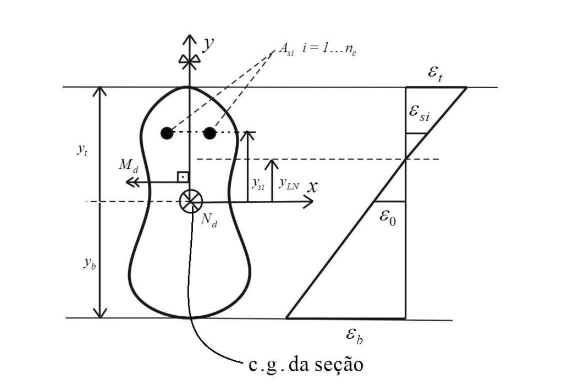

## Plotagem da Região Viável do ELU

clear
%concreto
C = 30;
fck = 30000000; %pa
e_cu = ecu(fck,C);
e_c2 = ec2(fck,C);

%definição geometria
h = 0.32;
b = 0.2;
yt = 0.16;
yb = -0.16;
y_min = -0.11;
y_max = 0.11;

diameter_s = 10*10^-3;

%posição das barras
ys = [-0.11 0 0.11];

As = pi*(diameter_s/2)^2;
nbarras = [2 2 2];

Asi = As*nbarras;

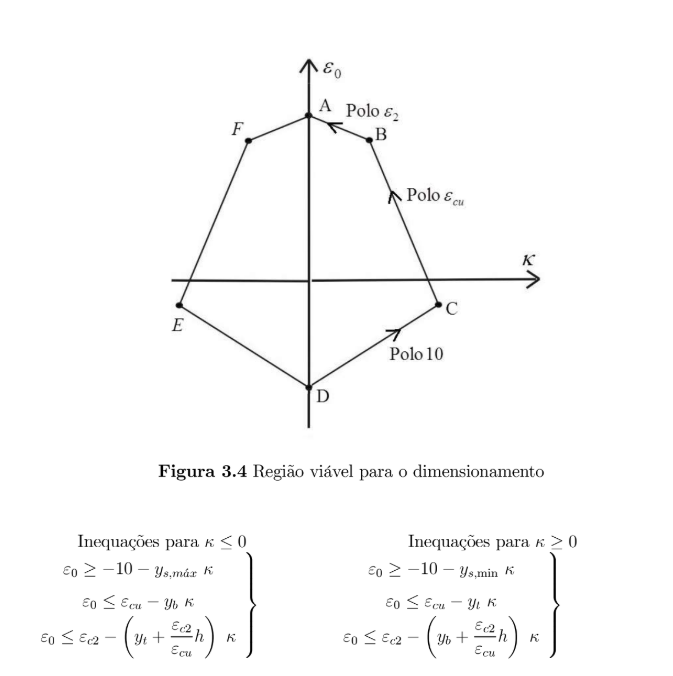

%As equações do livro para polo 2 estão errado, abaixo estão as corretas

%pontos a serem trabalhados

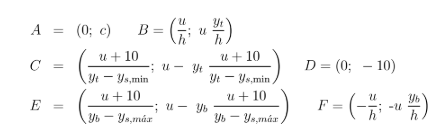

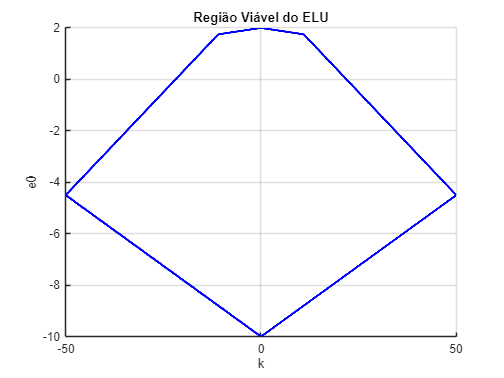

%definimos os pontos aqui e as retas:
Polo_10 = @(x,y) -10 -y*x;
Polo_Ecu = @(x,y) e_cu - y*x;
Polo_Ec2_esquerda = @(x,y) e_c2 - (y + h*(e_cu - e_c2)/e_cu)*x;
Polo_Ec2_direita = @(x,y) e_c2 - (y - h*(e_cu - e_c2)/e_cu)*x;

eixo_C = (e_cu+10)/(yt - y_min);
eixo_B = e_cu/h;
eixo_E = (e_cu+10)/(yb - y_max);
eixo_F = -e_cu/h;

%k
x_ab = linspace(0,eixo_B,1000);
x_bc = linspace(eixo_B, eixo_C,1000);
x_dc = linspace (0,eixo_C,1000);
x_de = linspace(eixo_E,0,1000);
x_ef = linspace(eixo_E,eixo_F,1000);
x_fa = linspace(eixo_F,0,1000);

% e0
y_ab = Polo_Ec2_direita(x_ab, yt);
y_bc = Polo_Ecu(x_bc, yt);
y_dc = Polo_10(x_dc, y_min);
y_de = Polo_10(x_de, y_max);
y_ef = Polo_Ecu(x_ef, yb);
y_fa = Polo_Ec2_esquerda(x_fa, yb);

% Plotar os gráficos
figure;
hold on;
plot(x_ab, y_ab, 'b-', 'LineWidth', 2); % Polo_Ec2 em x_ab
plot(x_bc, y_bc, 'b-', 'LineWidth', 2); % Polo_Ecu em x_bc
plot(x_dc, y_dc, 'b-', 'LineWidth', 2); % Polo_10 em x_dc
plot(x_de, y_de, 'b-', 'LineWidth', 2); % Polo_10 em x_de
plot(x_ef, y_ef, 'b-', 'LineWidth', 2); % Polo_Ecu em x_ef
plot(x_fa, y_fa, 'b-', 'LineWidth', 2); % Polo_Ec2 em x_fa
hold off;

% Configuração do gráfico
grid on;
title('Região Viável do ELU');
xlabel('k');
ylabel('e0');